# Práctica N°4 Control Biológico.

Autor: Tomás Vidal

### Notas

-

## Preguntas

- ¿Qué hacer cuando no deja simular 30 horas? (error de step)

- Tengo error muy grande con la exponencial a lazo abierto, es normal?

- En el control linealizante: ¿cuál era el motivo de ese denominador en la proporción del error?

- Control linealizante: variaciones en los parámetros, considero $\mu \left(s\right)$±20%?

## Proceso de respiración de *S. cerevisiae *con sistema de cultivo fed-batch


$$\[
\begin{cases} 
\dot{x} = \mu x - Dx \\ 
\dot{s} = -k\mu x + D(s_{in}-s) \\ 
\dot{V} = F_{in}
\end{cases}
\]$$



$$\[
\mu(s) = \mu_{\max} \frac{s}{s + K_s}
\]$$


DatosModeloTP4

sim_hours = 30; % la cantidad de horas que se van a simular
timeStep = 1e-2;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

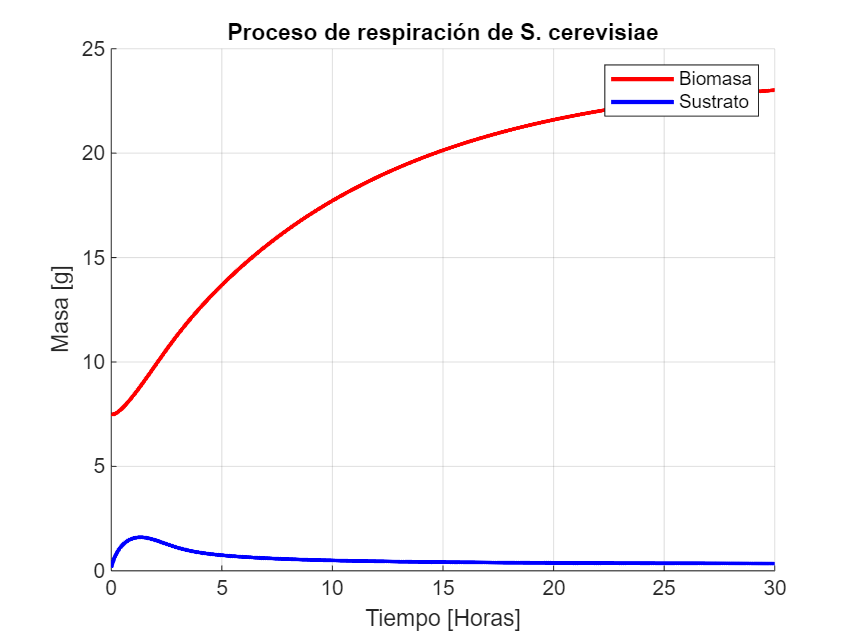

D=0.1;
params={1};
for i=1:length(params)

    sim_out = sim('TP4', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de respiración de S. cerevisiae');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

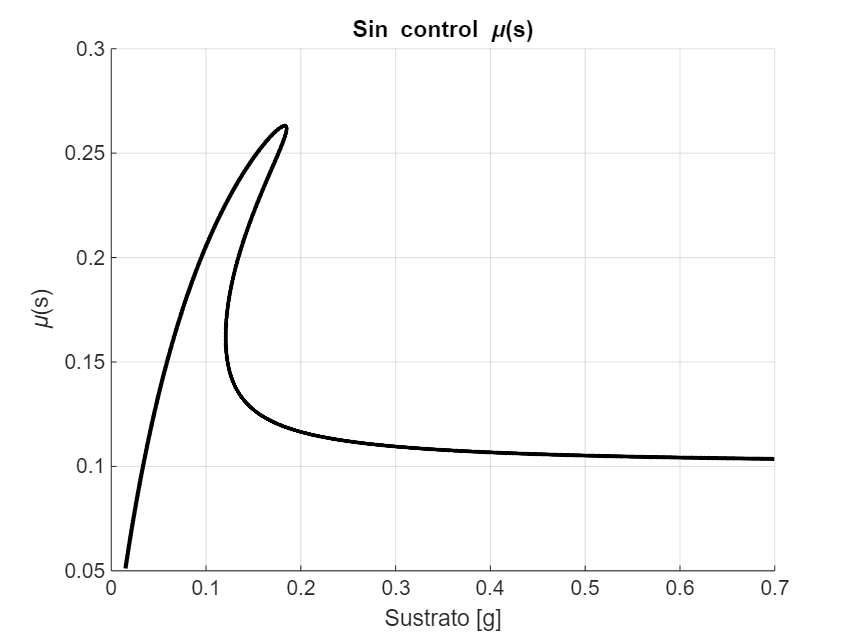


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Sin control \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate.*volume, mu, 'k', 'LineWidth', 2);

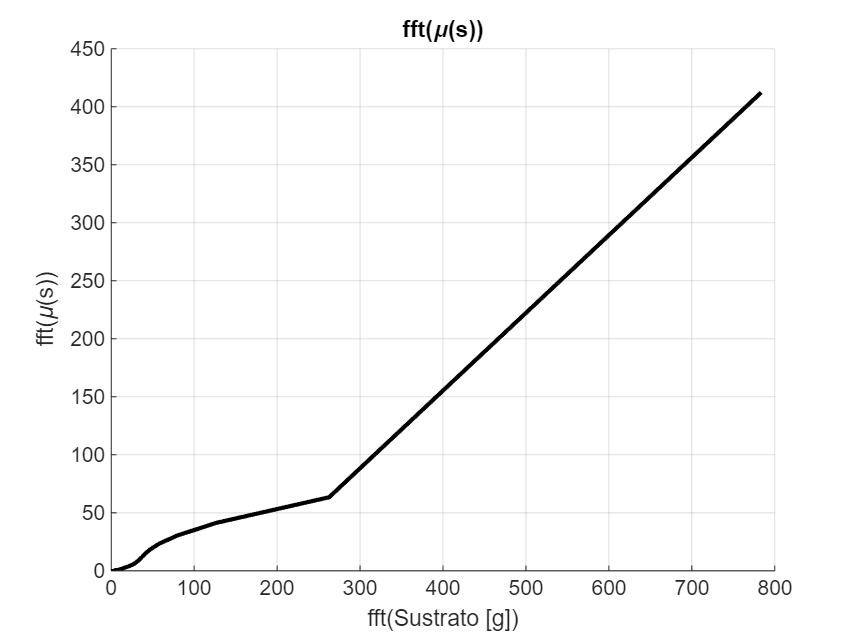


[mu_freq1] = abs(fft(mu));
[s_freq1] = abs(fft(sustrate.*volume));

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('fft(\mu(s))');
xlabel('fft(Sustrato [g])');
ylabel('fft(\mu(s))');
plot(s_freq1, mu_freq1, 'k', 'LineWidth', 2);

## Control exponencial a lazo abierto

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.126;
modelParameters.mu_r=mu_r;

params={0};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_x0 = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Resultados

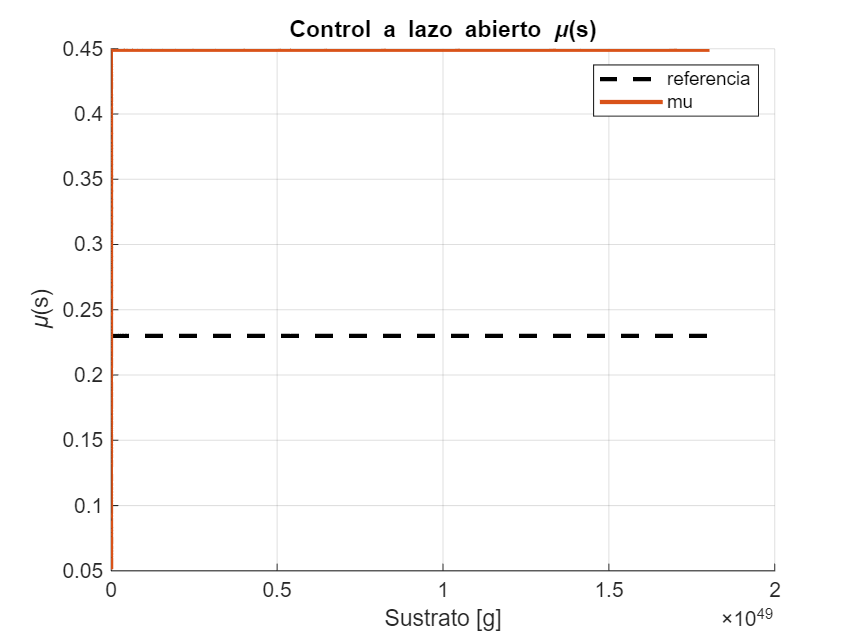

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_x0, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_x0, mus{1}, 'LineWidth', 2);

legend('referencia', 'mu');

Errores relativos

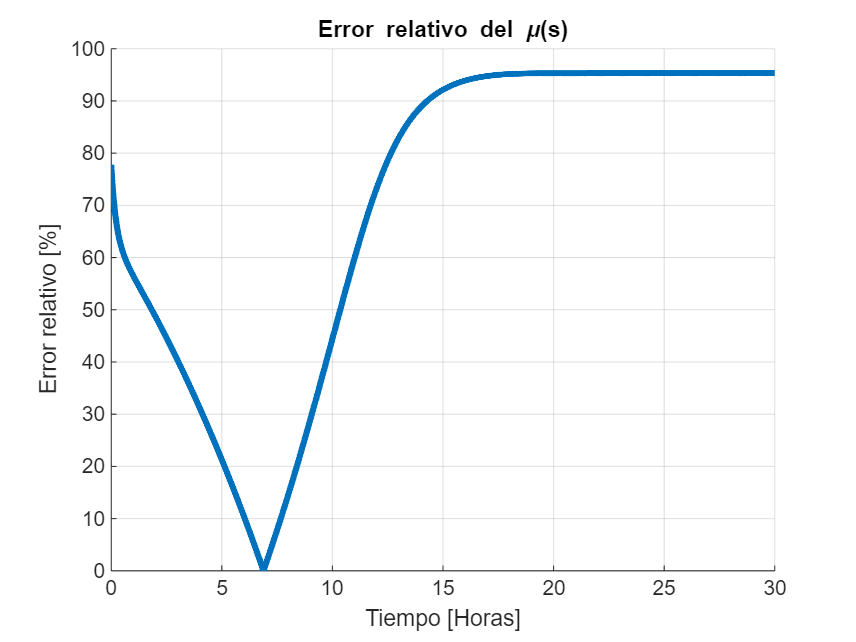

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);

## Variaciones en los parámetros

### Incertidumbre en x0

Controlado con C(s)=Kp y variaciones en las condiciones iniciales:

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params={x0*(1.2),x0*(0.8)}; % más/menos 20% del x0
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    modelParameters.x0=params{i};

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_x0 = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Ahora se muestran los resultados, comparando el caso cuando se tiene variaciones en las condiciones iniciales y como los controadores empleados responden a estas variaciones, es decir su robustez.

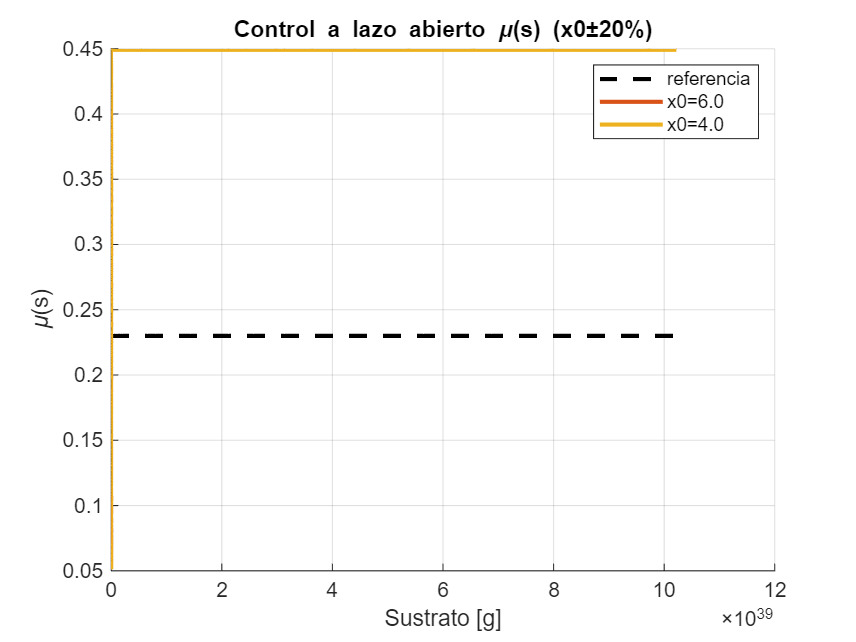

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s) (x0±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_x0, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_x0, mus{1}, 'LineWidth', 2);
plot(sustrate_x0, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('x0=%.1f', params{1}), ...
    sprintf('x0=%.1f', params{2}));

Errores relativos

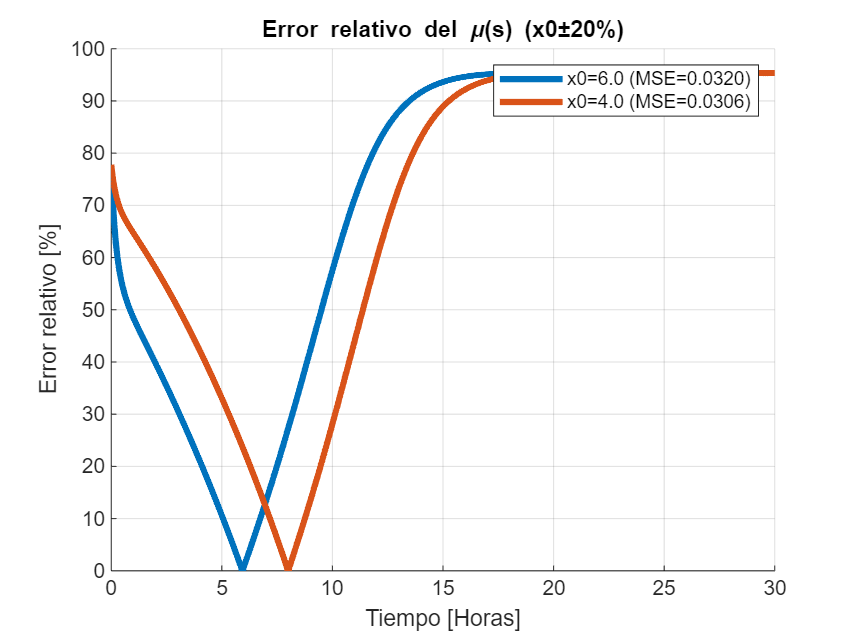

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.4f)', params{2}, MSE{2}));

Ambos terminan convergiendo a pesar de tener un error en el valor inicial.

### Incertidumbre en ks 

Ahora hago lo mismo que antes pero variando $k_s$

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params_ks={ks*(1.2),ks*(0.8)}; % más/menos 20% del ks
mus_ks=cell(length(params_ks));
error_ks=cell(length(params_ks));
MSE_ks=cell(length(params_ks));
for i=1:length(params_ks)
    modelParameters.K = [1;-params_ks{i}];

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_ks = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus_ks{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus_ks{i}))*mu_r;
 
    error_ks{i}=(mu_r_vector-mus_ks{i});
    MSE_ks{i} = immse(reshape(mu_r_vector, size(mus_ks{i})), mus_ks{i});
end

Ahora se muestran las gráficas

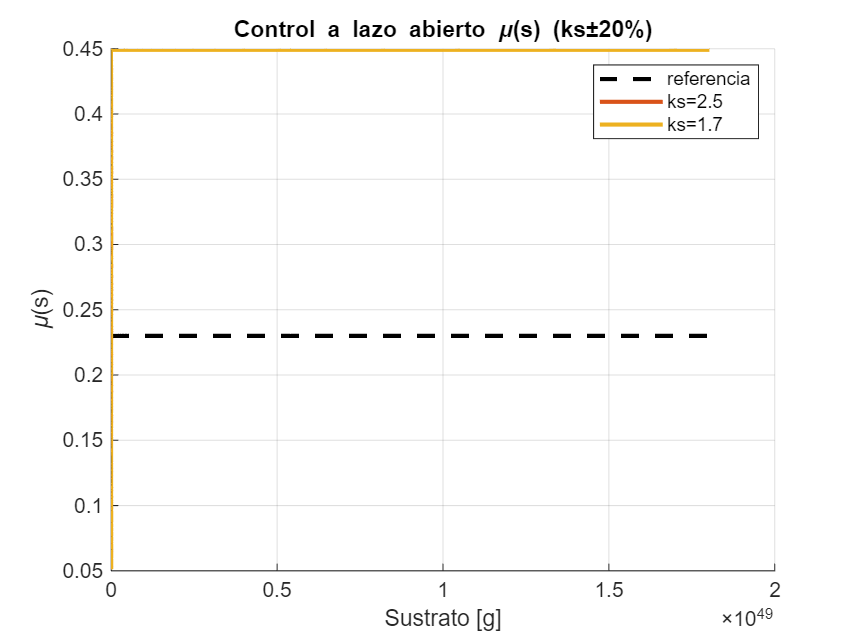

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s) (ks±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_ks, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_ks, mus_ks{1}, 'LineWidth', 2);
plot(sustrate_ks, mus_ks{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ks=%.1f', params_ks{1}), ...
    sprintf('ks=%.1f', params_ks{2}));

Y las del error relativo son:

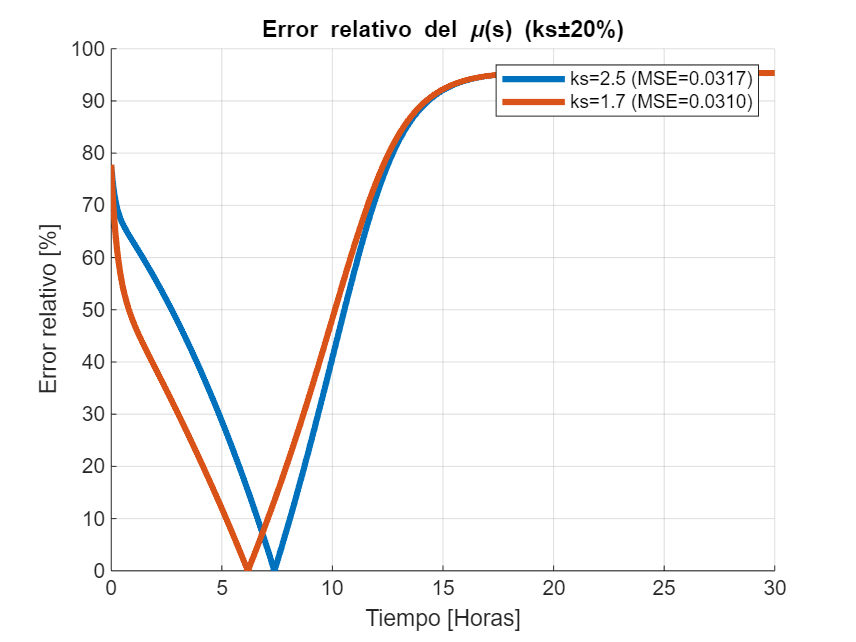

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error_ks{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error_ks{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ks=%.1f (MSE=%.4f)', params_ks{1}, MSE_ks{1}), ...
    sprintf('ks=%.1f (MSE=%.4f)', params_ks{2}, MSE_ks{2}));

Viendo los resultados, se podría concluir que es más robusto ante variaciones en $k_s$

### Incertidumbre en Ks

Ahora hago lo mismo que antes pero variando $K_s$

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params_Ks={Ks*(1.2),Ks*(0.8)}; % más/menos 20% del ks
mus_Ks=cell(length(params_Ks));
error_Ks=cell(length(params_Ks));
MSE_Ks=cell(length(params_Ks));
for i=1:length(params_Ks)
    modelParameters.mu_model.Ks=Ks;

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_Ks = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus_Ks{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus_Ks{i}))*mu_r;
 
    error_Ks{i}=(mu_r_vector-mus_Ks{i});
    MSE_Ks{i} = immse(reshape(mu_r_vector, size(mus_Ks{i})), mus_Ks{i});
end

Ahora se muestran las gráficas

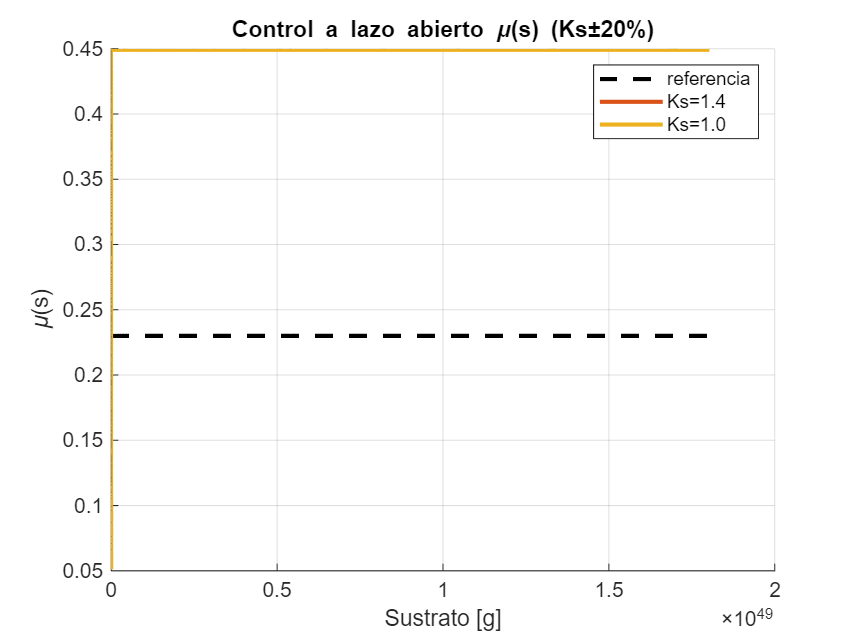

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s) (Ks±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_Ks, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_Ks, mus_Ks{1}, 'LineWidth', 2);
plot(sustrate_Ks, mus_Ks{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('Ks=%.1f', params_Ks{1}), ...
    sprintf('Ks=%.1f', params_Ks{2}));

Y las del error relativo son:

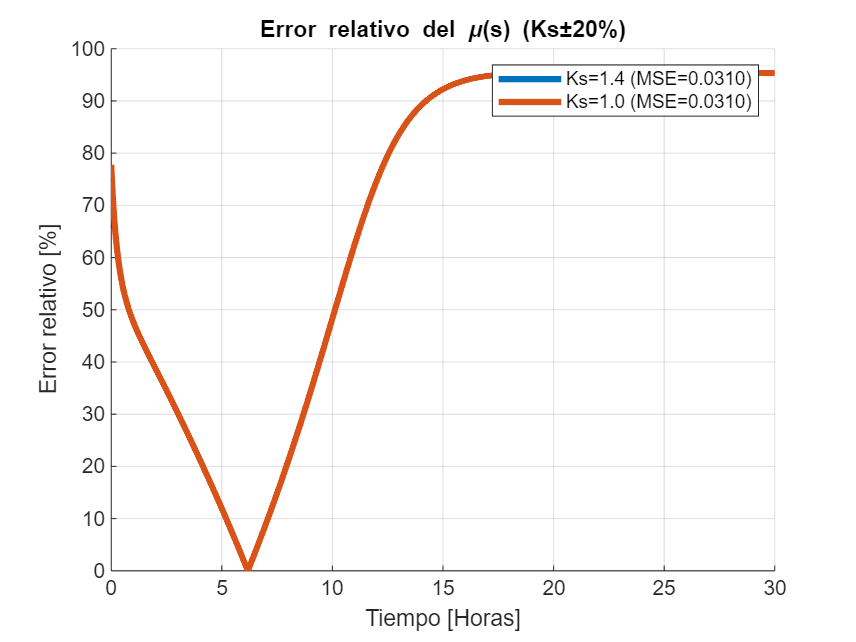

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (Ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error_Ks{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error_Ks{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('Ks=%.1f (MSE=%.4f)', params_Ks{1}, MSE_Ks{1}), ...
    sprintf('Ks=%.1f (MSE=%.4f)', params_Ks{2}, MSE_Ks{2}));

Viendo los resultados, se podría concluir que es indiferente a variaciones de $K_s$, por lo que es muy buen control para cuando hay incertidumbre en este parámetro

## Control a lazo cerrado

### Control proporcional al error

Ahora trato de implementar una ley de alimentación exponencial a lazo cerrado

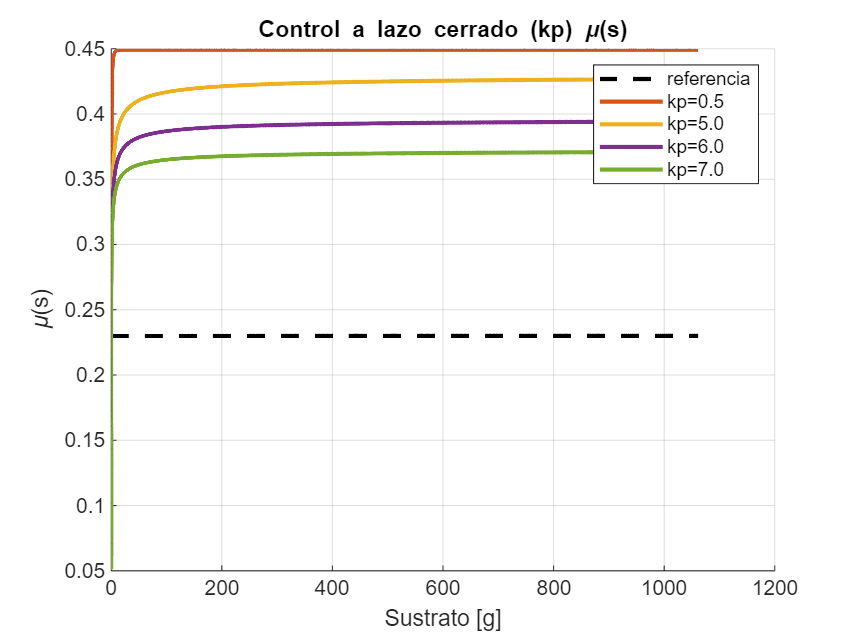

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
% modelParameters.kp=0.1; % factor proporcional

params={0.5,5,6,7};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp=params{i};

    sim_out = sim('TP4_control_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp) \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('kp=%.1f', params{1}), ...
    sprintf('kp=%.1f', params{2}), ...
    sprintf('kp=%.1f', params{3}), ...
    sprintf('kp=%.1f', params{4}));

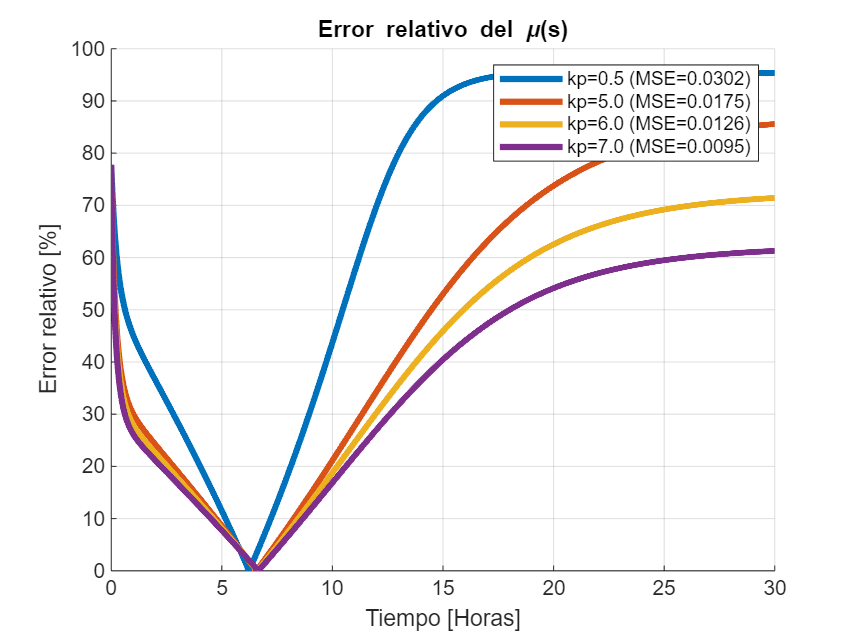


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('kp=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{4}, MSE{4}));

### Proporcional integrativo

Ahora agrego un término integrativo

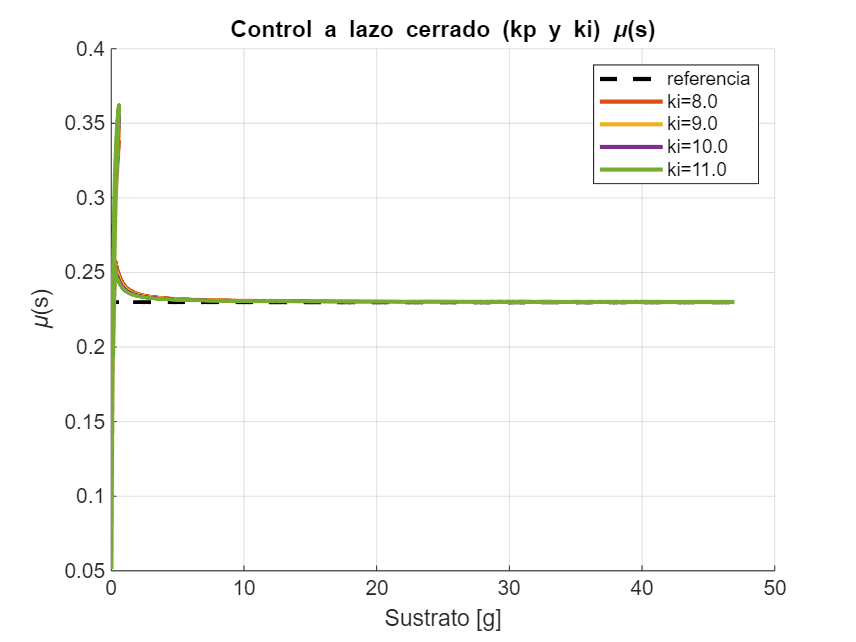

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
% modelParameters.ki=0.1; % factor integrativa
e0=mu_r*1.5;

params={8, 9, 10, 11};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ki=params{i};

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ki=%.1f', params{1}), ...
    sprintf('ki=%.1f', params{2}), ...
    sprintf('ki=%.1f', params{3}), ...
    sprintf('ki=%.1f', params{4}));

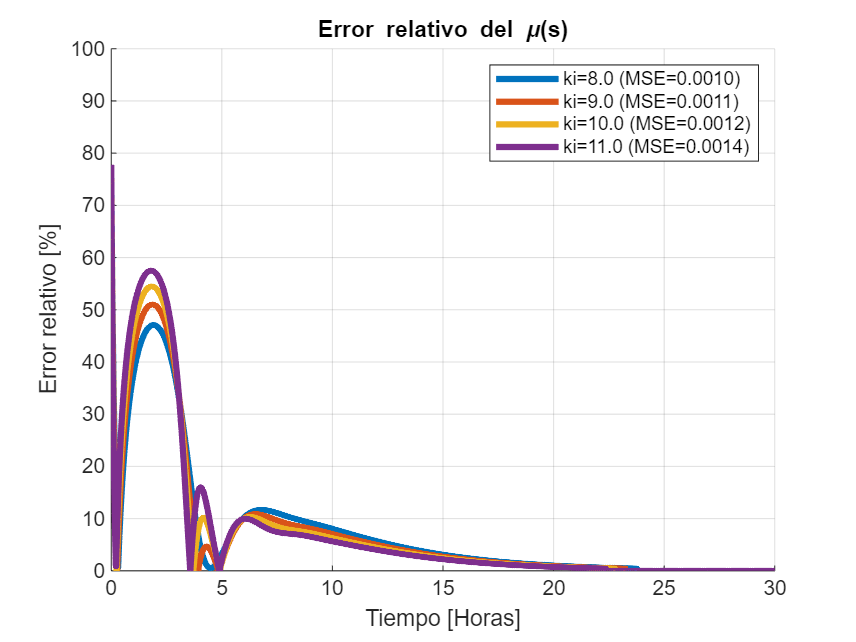


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{4}, MSE{4}));

## Robustez del controlador a lazo cerrado (integrador)

Se comprueba la robustez al igual que antes, pero solo para el caso donde se tiene un integrador

### Variaciones en x0

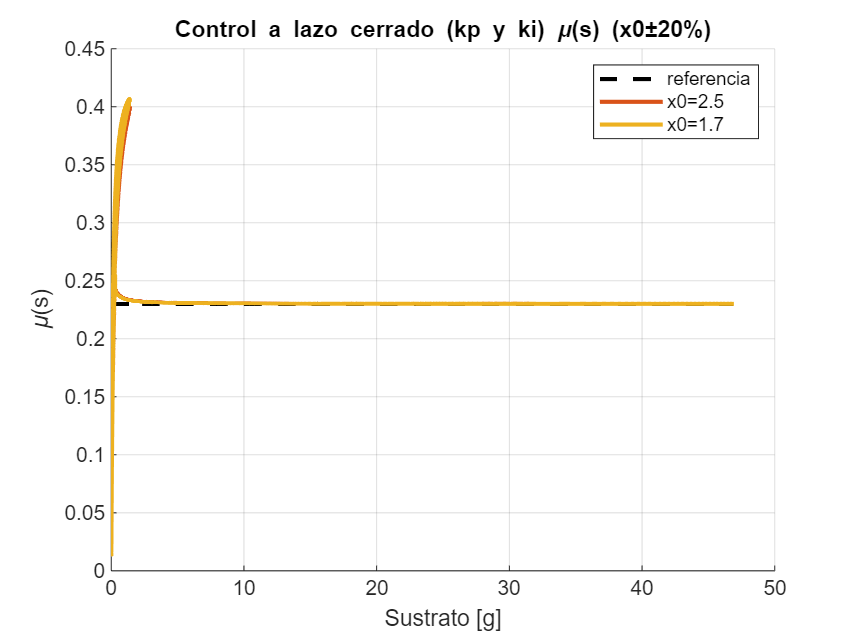

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
modelParameters.ki=11; % factor integrativa
e0=mu_r*1.5;

params_x0={ks*(1.2),ks*(0.8)}; % más/menos 20% del ks
mus=cell(length(params_x0));
error=cell(length(params_x0));
MSE=cell(length(params_x0));
for i=1:length(params_x0)
    modelParameters.x0=params{i};

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s) (x0±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('x0=%.1f', params_x0{1}), ...
    sprintf('x0=%.1f', params_x0{2}));

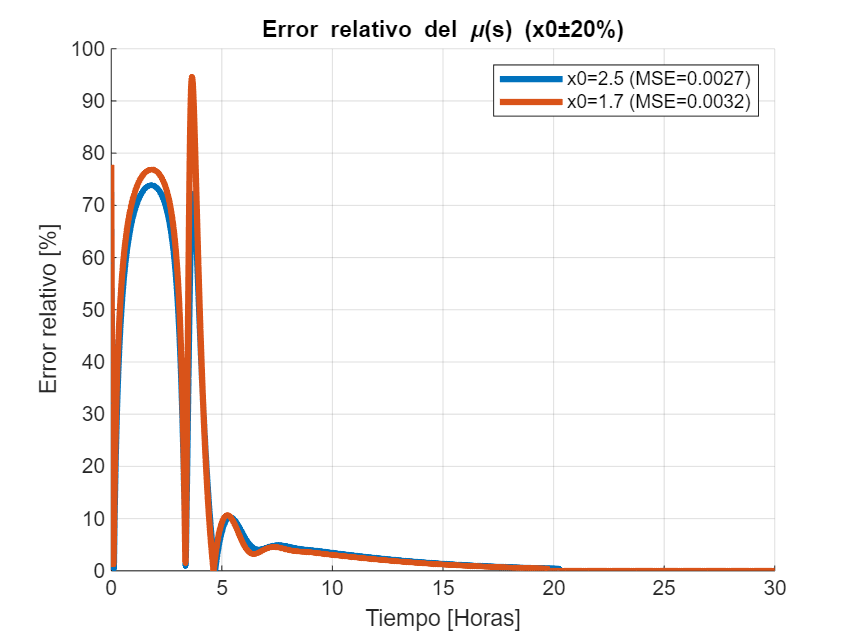


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.4f)', params_x0{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.4f)', params_x0{2}, MSE{2}));

### Variaciones en ks

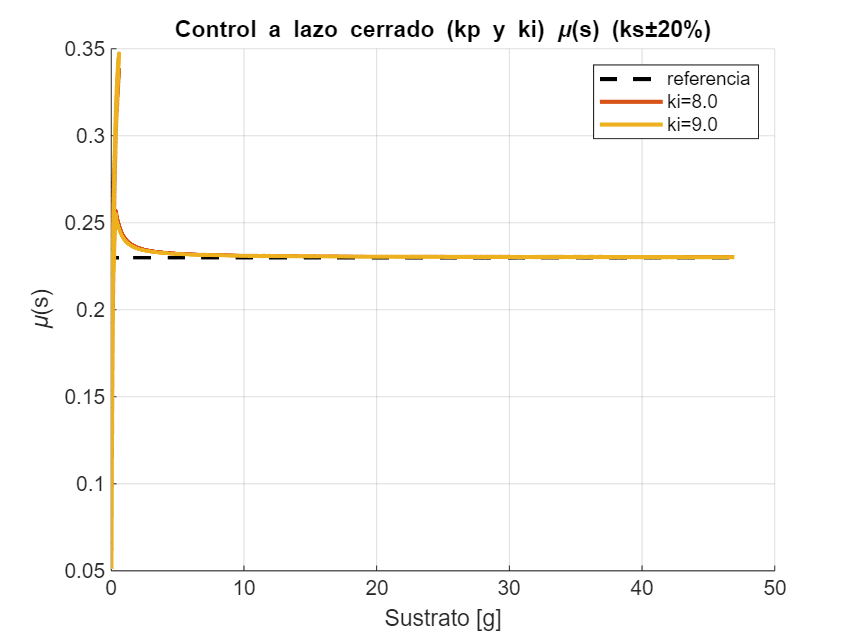

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
modelParameters.ki=11; % factor integrativa
e0=mu_r*1.5;

params={8, 9, 10, 11};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ki=params{i};

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s) (ks±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ki=%.1f', params{1}), ...
    sprintf('ki=%.1f', params{2}));

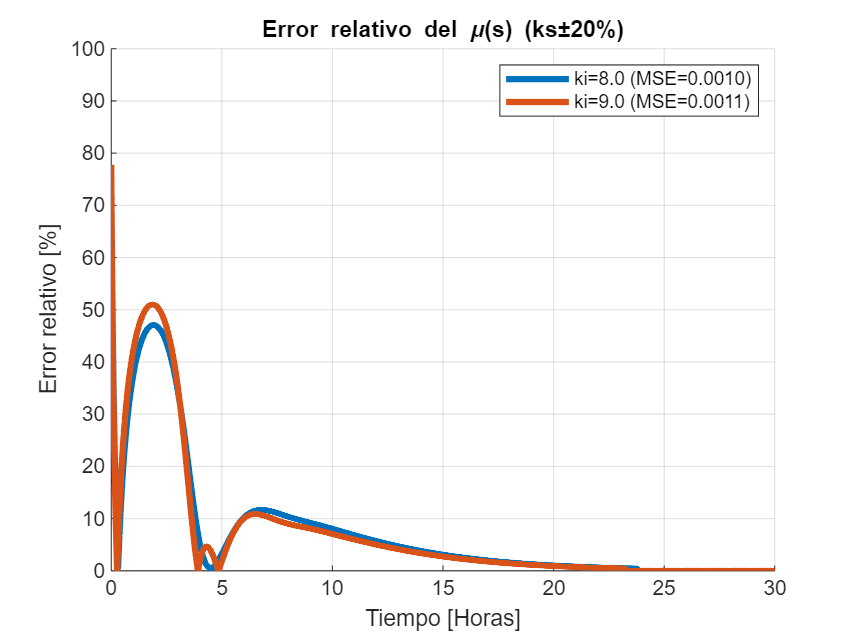


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{2}, MSE{2}));

### Variaciones en Ks

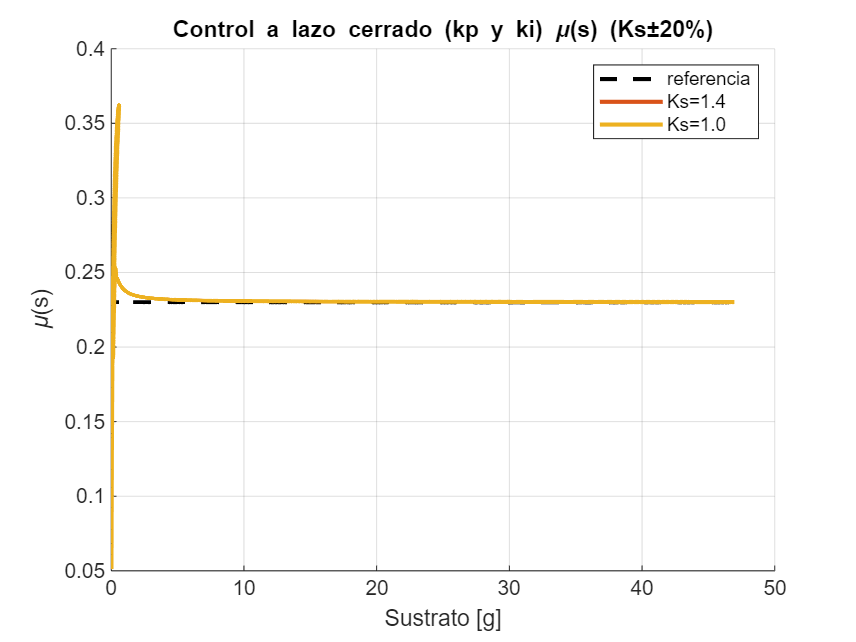

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
modelParameters.ki=11; % factor integrativa
e0=mu_r*1.5;

params_Ks={Ks*(1.2),Ks*(0.8)}; % más/menos 20% del ks
mus=cell(length(params_Ks));
error=cell(length(params_Ks));
MSE=cell(length(params_Ks));
for i=1:length(params_Ks)
    modelParameters.mu_model.Ks=Ks;

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s) (Ks±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('Ks=%.1f', params_Ks{1}), ...
    sprintf('Ks=%.1f', params_Ks{2}));

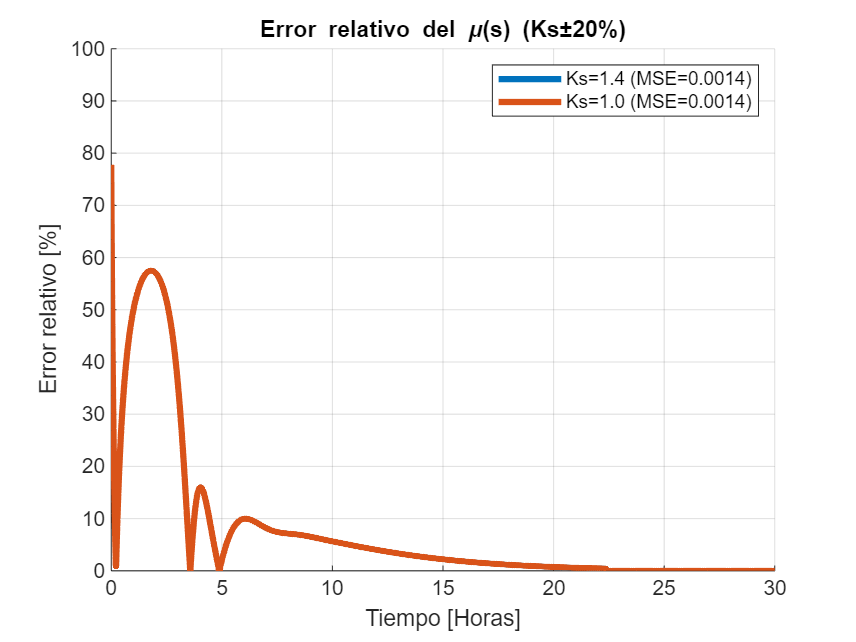


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (Ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('Ks=%.1f (MSE=%.4f)', params_Ks{1}, MSE{1}), ...
    sprintf('Ks=%.1f (MSE=%.4f)', params_Ks{2}, MSE{2}));

## Modelo cinético de Haldane

Se simula el sistema sin control. Para ver como se comporta $\mu \left(s\right)$ y así poder calcular el $s_r$

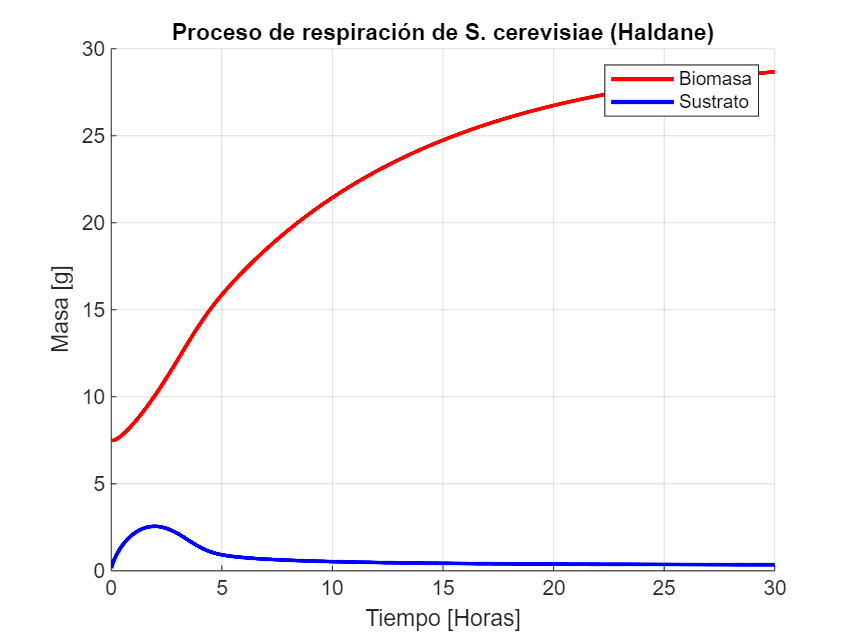

D=0.1;
params={1};
for i=1:length(params)

    sim_out = sim('TP4_Haldane', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mu))*mu_r;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de respiración de S. cerevisiae (Haldane)');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

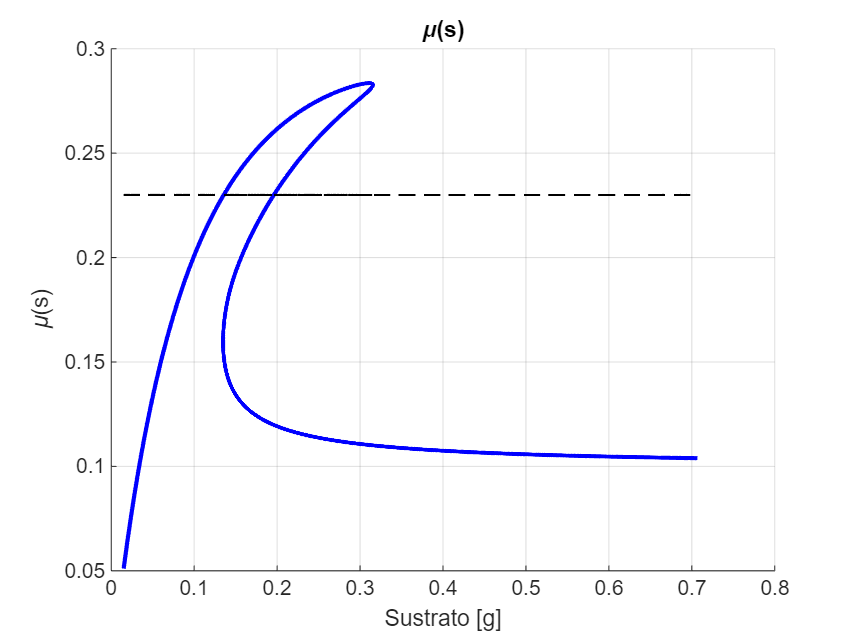


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate.*volume, mu, 'b', 'LineWidth', 2);
plot(sustrate.*volume, mu_r_vector, '--k', 'LineWidth', 1);

## Control con modelo de Haldane

### Control a lazo abierto

modelParameters.s_in=s_in;
modelParameters.x0=x0;
% modelParameters.s_r = 0.126;
modelParameters.mu_r=mu_r;

params={0.126, 1.3, 1.4, 1.5, 1.6, 1.7};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.s_r = params{i};

    sim_out = sim('TP4_control_LA_Haldane', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Resultados

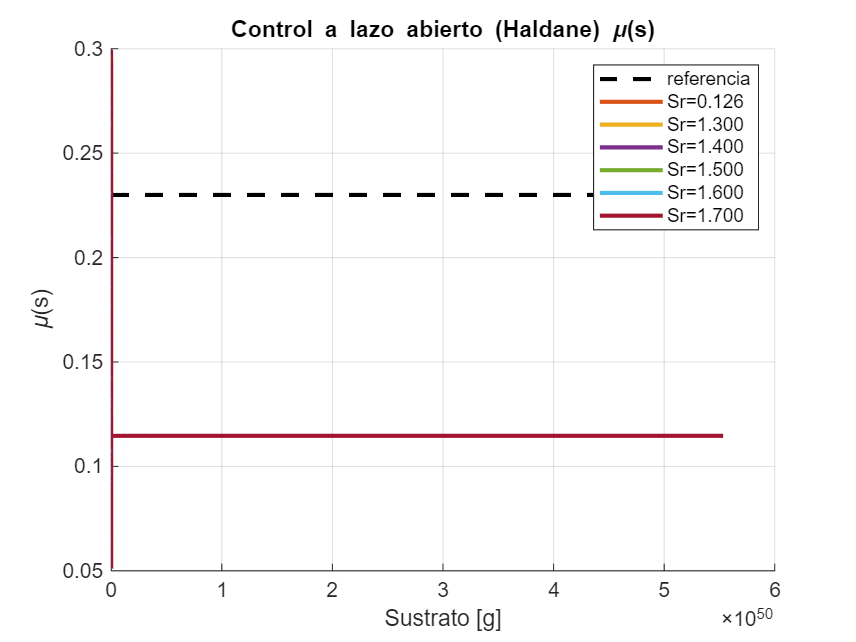

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto (Haldane) \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);
plot(sustrate, mus{5}, 'LineWidth', 2);
plot(sustrate, mus{6}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('Sr=%.3f', params{1}), ...
    sprintf('Sr=%.3f', params{2}), ...
    sprintf('Sr=%.3f', params{3}), ...
    sprintf('Sr=%.3f', params{4}), ...
    sprintf('Sr=%.3f', params{5}), ...
    sprintf('Sr=%.3f', params{6}));

Errores relativos

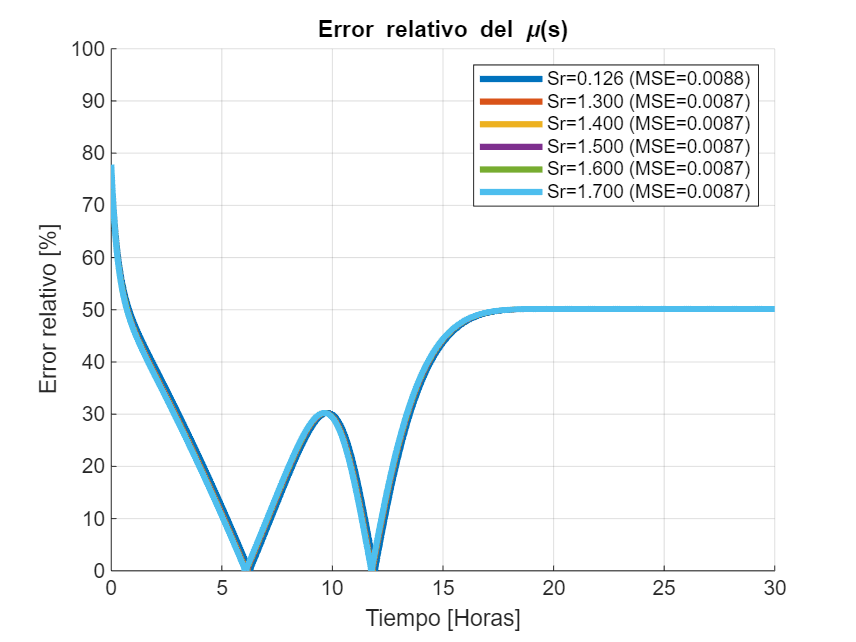

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{5}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{6}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('Sr=%.3f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{4}, MSE{4}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{5}, MSE{5}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{6}, MSE{6}));

### Control a lazo cerrado Haldane (integrador)

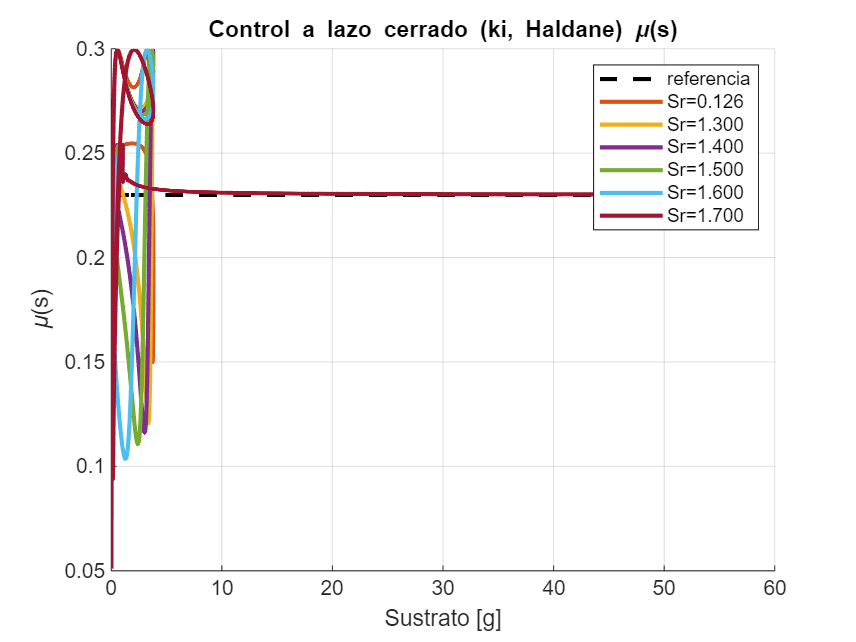

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
modelParameters.ki=9; % factor integrativa
e0=mu_r*1.5;

params={0.126, 1.3, 1.4, 1.5, 1.6, 1.7};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.s_r = params{i};

    sim_out = sim('TP4_control_int_Haldane', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (ki, Haldane) \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);
plot(sustrate, mus{5}, 'LineWidth', 2);
plot(sustrate, mus{6}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('Sr=%.3f', params{1}), ...
    sprintf('Sr=%.3f', params{2}), ...
    sprintf('Sr=%.3f', params{3}), ...
    sprintf('Sr=%.3f', params{4}), ...
    sprintf('Sr=%.3f', params{5}), ...
    sprintf('Sr=%.3f', params{6}));

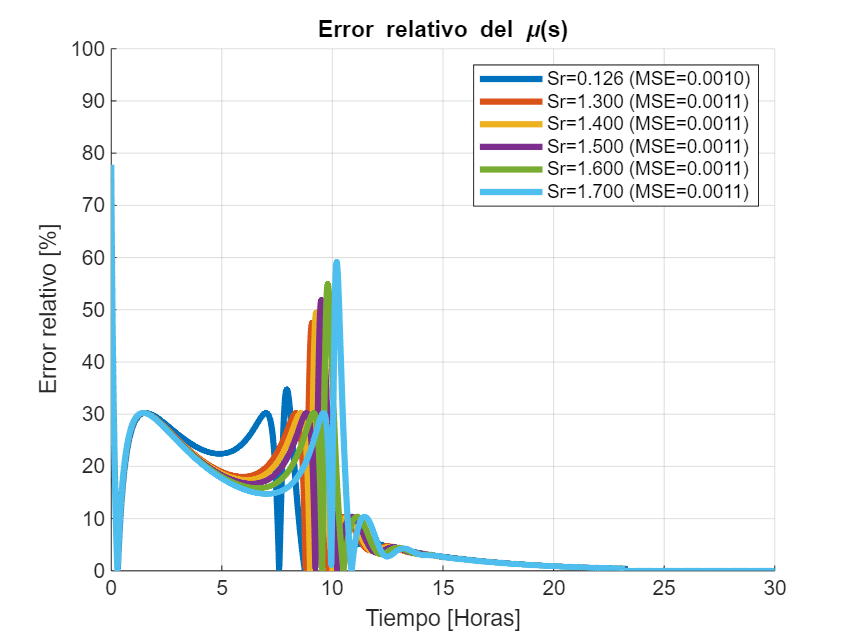


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{5}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{6}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('Sr=%.3f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{4}, MSE{4}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{5}, MSE{5}), ...
    sprintf('Sr=%.3f (MSE=%.4f)', params{6}, MSE{6}));


% Sustrato
% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('TEST');
% xlabel('Sustrato [g]');
% plot(time, sustrate, 'LineWidth', 2);

## Control linealizante

Se quiere regular la concentración de sustrato implementando un control linealizante

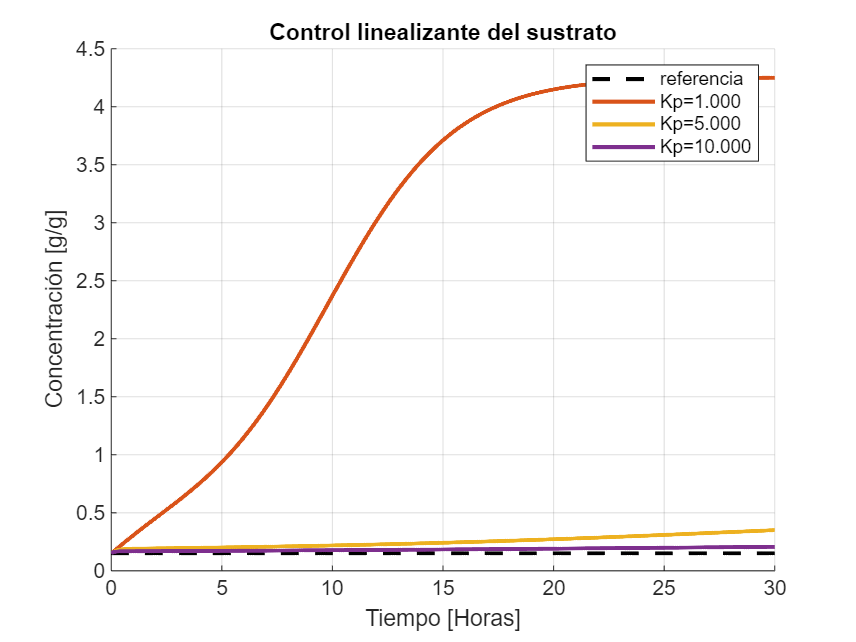

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
% modelParameters.kp=5; % factor proporcional

params={1,5,10};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp = params{i};

    sim_out = sim('TP4_control_linealizante', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('Kp=%.3f', params{1}), ...
    sprintf('Kp=%.3f', params{2}), ...
    sprintf('Kp=%.3f', params{3}));

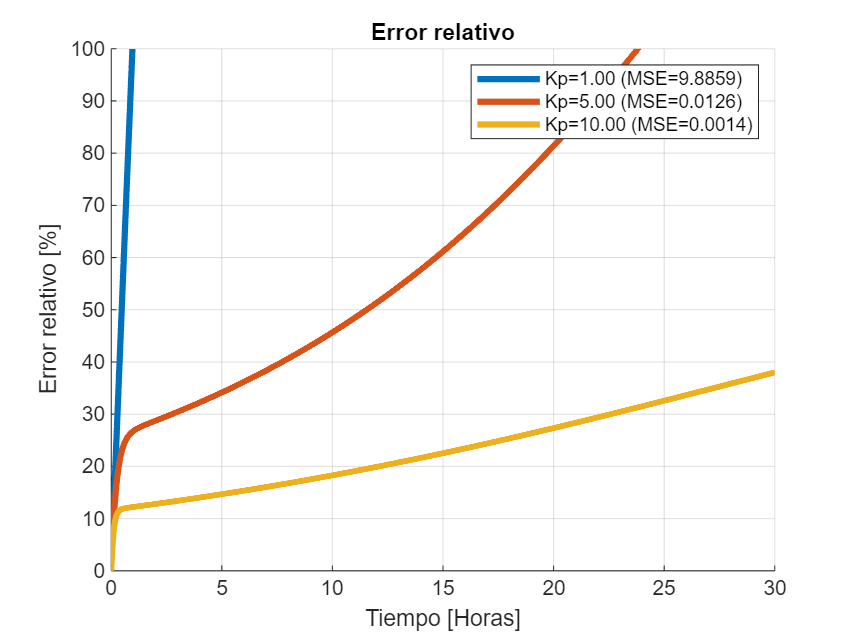


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('Kp=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('Kp=%.2f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('Kp=%.2f (MSE=%.4f)', params{3}, MSE{3}));

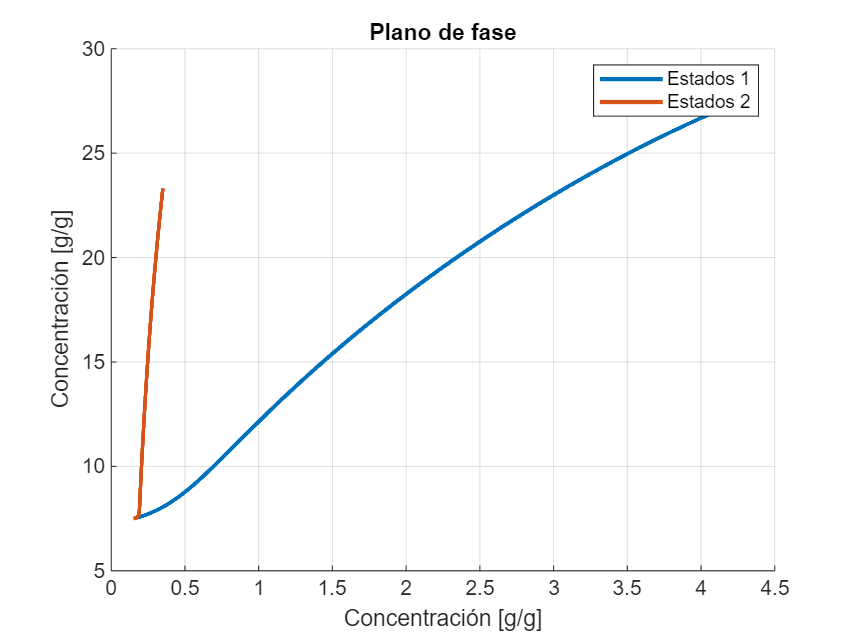


% Plano de fase
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Plano de fase');
xlabel('Concentración [g/g]');
ylabel('Concentración [g/g]');
plot(sustrates{1}, biomass{1}, 'LineWidth', 2);
plot(sustrates{2}, biomass{2}, 'LineWidth', 2);

legend('Estados 1', 'Estados 2');

### Control linealizante con variaciones en los parámetros

Que pasa si se tienen variaciones del 20% en los parámetros del controlador

### Variaciones en ks

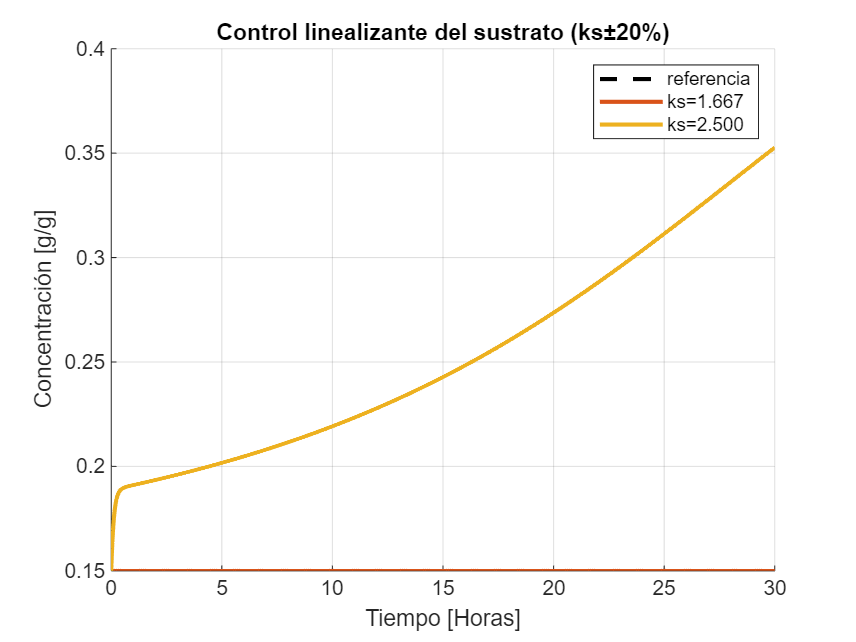

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=10; % factor proporcional

params={ks*(0.8), ks*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks = params{i};

    sim_out = sim('TP4_control_linealizante', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('ks=%.3f', params{1}), ...
    sprintf('ks=%.3f', params{2}));

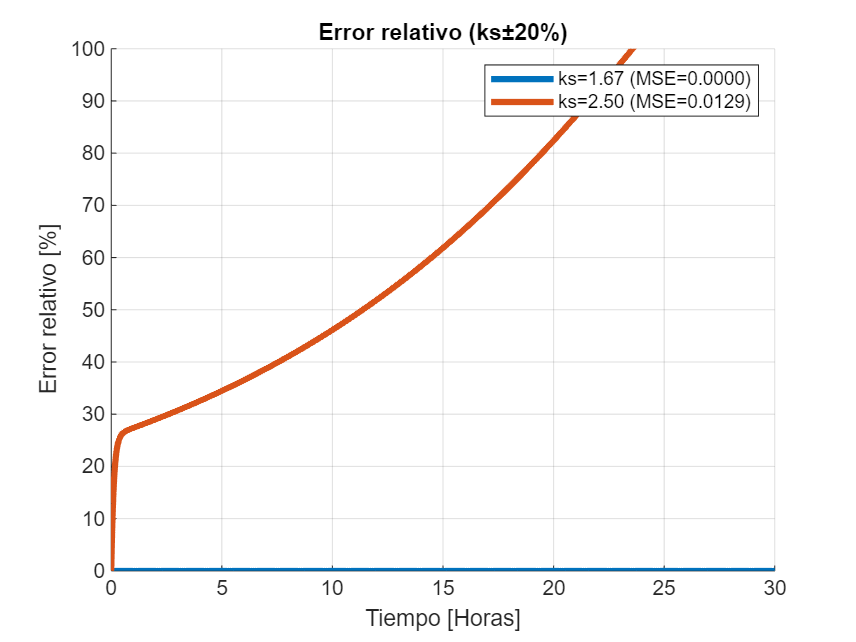


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks=%.2f (MSE=%.4f)', params{2}, MSE{2}));

Es muy dependiente de ks. Varía demasiado. Pero se puede arreglar bastante con un ajuste proporcional (kp)

### Variaciones en Ks con el modelo de Haldane (en simulacion)

Se emplea el modelo de Monod para diseñar el controlador, pero se simula empleando el modelo cinético de Haldane

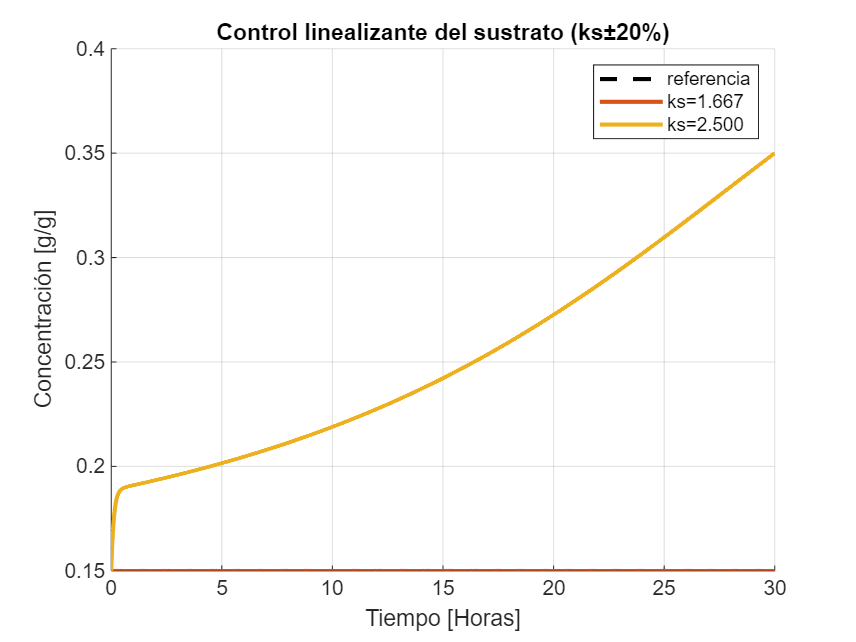

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=10; % factor proporcional

params={ks*(0.8), ks*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks = params{i};

    sim_out = sim('TP4_control_linealizante_Haldane', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('ks=%.3f', params{1}), ...
    sprintf('ks=%.3f', params{2}));

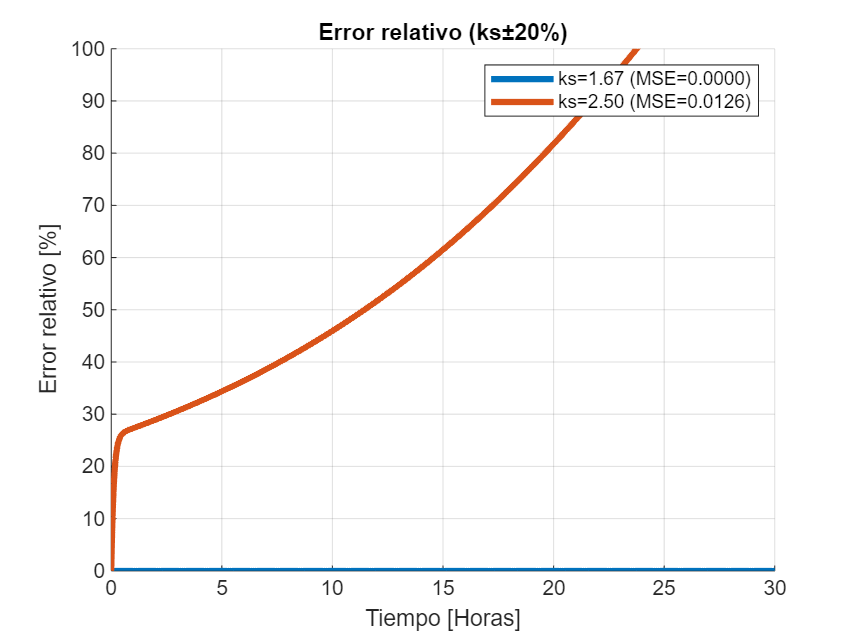


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks=%.2f (MSE=%.4f)', params{2}, MSE{2}));

### No se el consumo de sustrato

El consumo de sustrato es $q_s =k*\mu \left(s\right)$, y se asume desconocido. Por lo que simplemente lo ignoro del controlador

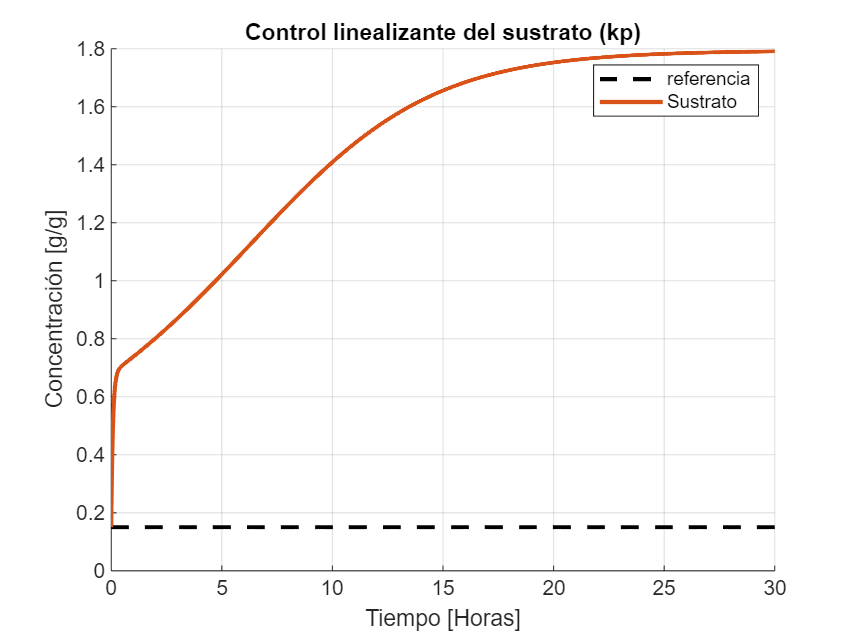

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=10; % factor proporcional

params={0};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks = params{i};

    sim_out = sim('TP4_control_linealizante_Haldane_params_desconocidos', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);

legend('referencia', 'Sustrato');

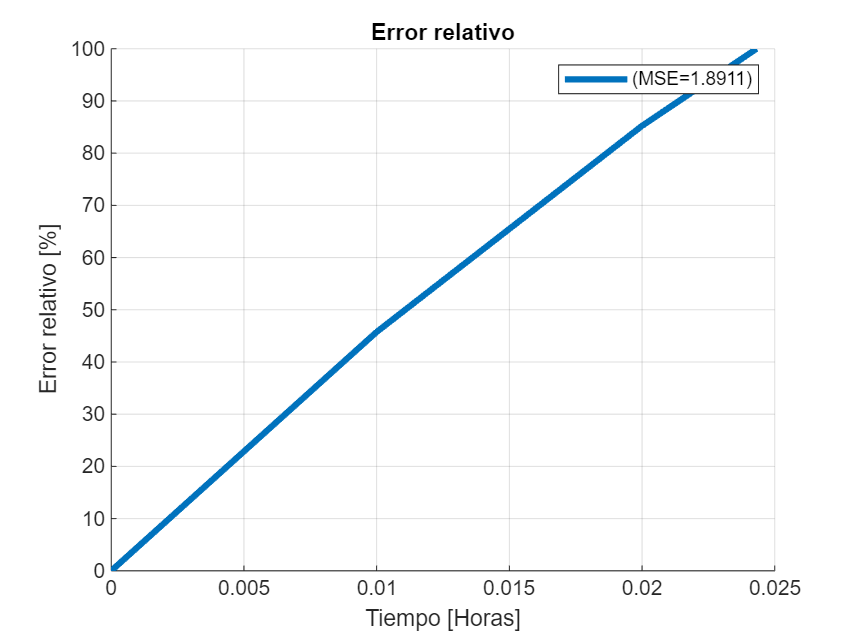


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', MSE{1}));

Al ignorar este término, efectivemente lo que ocurre es que incrementa el error al estado estacionario. Por lo que incluyo un integrador

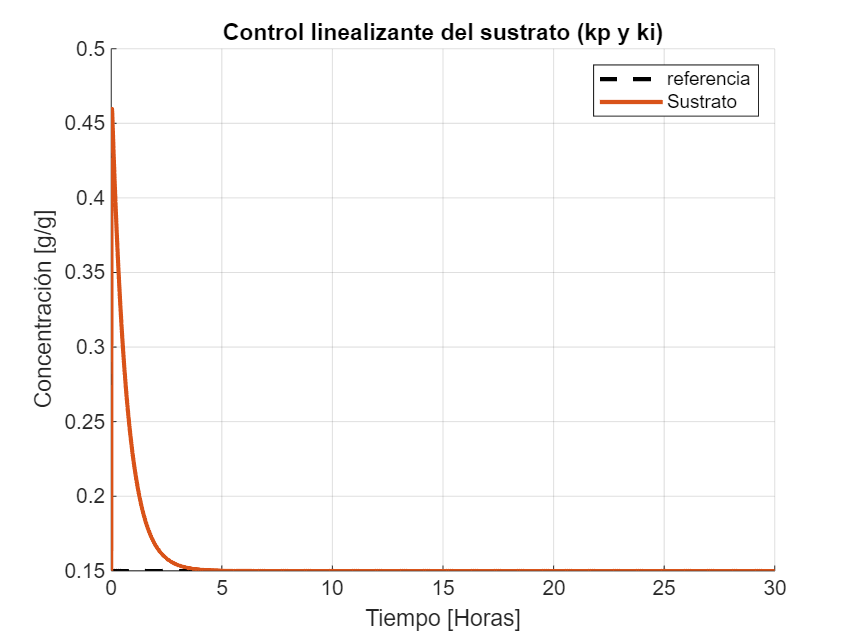

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=10; % factor proporcional
modelParameters.ki=15; % factor integral
e0=s_r*1.5; % CI integrador del error

params={0};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks = params{i};

    sim_out = sim('TP4_control_linealizante_Haldane_params_desconocidos_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp y ki)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);

legend('referencia', 'Sustrato');

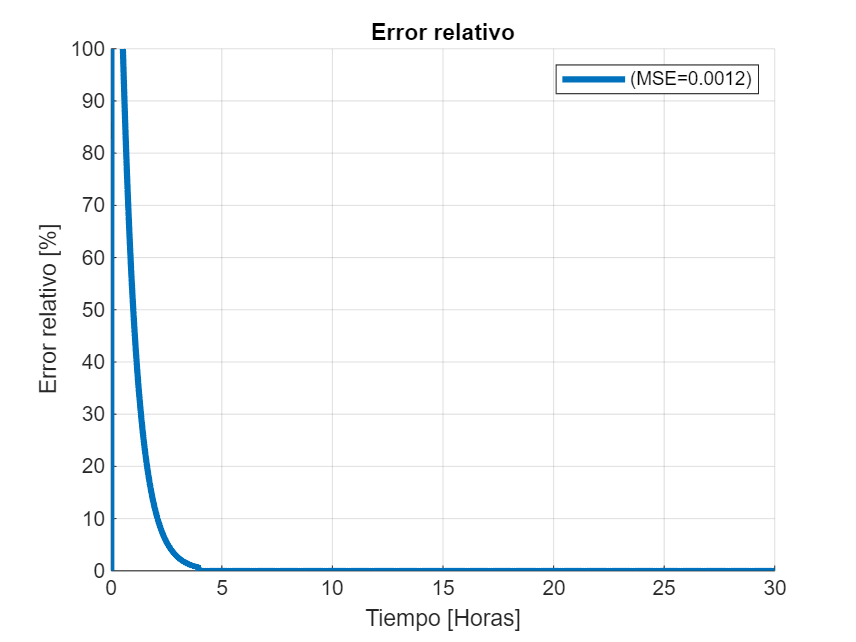


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', MSE{1}));

Lo que hice fue considerar que el error es proporcional e integrativo con respecto a los parámetros que si puedo medir, entonces ahí el error se eliminó por completo en el estado estacionario